# **HeumanLambda**

 Heuman Lambda function 

## Definition 

$\Lambda_0 \left(\beta \left|m\right.\right)\equiv \frac{2\left(1-m\right)\;\sin \beta \;\cos \beta }{\pi \sqrt{1-\left(1-m\right)\sin^2 \beta }}\Pi \left(\frac{m}{1-\left(1-m\right)\sin^2 \beta }\left|m\right.\right)$,   $\left|\beta \right|\le \pi /2$


$$\Lambda_0 \left(\beta ,k\right)\equiv \Lambda \left(\beta \left|k^2 \right.\right)$$


$\beta$ is the parametric angle (in radians), *k *is the modulus, *m *is the parameter, $\Pi \left(x|m\right)$ is the complete elliptic integral of the third kind ([1]). $\Lambda_0 \left(\beta \left|m\right.\right)$ is Heuman's form of the complete elliptic integral of the third kind.

Domain: $1-\left(1-m\right){\mathrm{sin}}^2 \beta \ge 0$ and  $m\le 1$. If  $0\le m\le 1$  (or $|k|\le 1$) then $-\infty \le \beta \le \infty$ (quasi periodic function). If $m<0$ then $|\beta |<{\mathrm{sin}}^{-1} \left(1/\sqrt{1-m}\right)$. For the specified domain, the  codomain  is the set of real numbers.

Basic features:

$\Lambda_0 \left(-\beta \left|m\right.\right)=-\Lambda_0 \left(\beta \left|m\right.\right)$   (odd)

$\Lambda_0 \left(n\pi \pm \beta \left|m\right.\right)=2n\pm \Lambda_0 \left(\beta \left|m\right.\right)$,   $|\beta |\le \pi /2$   (quasi-periodic)

Special values:

$\Lambda_0 \left(0\left|m\right.\right)=0$,   $\Lambda_0 \left(\frac{\pi }{2}\left|m\right.\right)=1$

  
$$\Lambda_0 \left(\beta \left|0\right.\right)=\sin \beta$$


Identities:

  
$$\Lambda_0 \left(\beta \left|m\right.\right)=\frac{2}{\pi }\left\lbrack K\left(m\right)E\left(\beta \left|1-m\right.\right)-\left(K\left(m\right)-E\left(m\right)\right)F\left(\beta \left|1-m\right.\right)\right\rbrack$$


  
$$\Lambda_0 \left(\beta \left|m\right.\right)=\frac{2}{\pi }K\left(m\right)\mathit{\mathbf{Z}}\left(\beta \left|1-m\right.\right)+\frac{F\left(\beta \left|1-m\right.\right)}{K\left(1-m\right)}$$


$F\left(\beta \left|m\right.\right)$, $E\left(\beta \left|m\right.\right)$ are Legendre incomplete complete elliptic integrals of the first kind and the second kind, and $K\left(m\right)\;$is complete integral of the first kind,  $\mathit{\mathbf{Z}}\left(\beta \left|m\right.\right)$ is second form of the Jacobi Zeta function.

## Syntax

Y = HeumanLambda(BETA,K)

y = hlambda(beta,k)

Y = mHeumanLambda(BETA,M)

y = mhlambda(beta,m)

## Description

**Y = HeumanLambda(BETA,K)** returns the Jacobi form of the elliptic integral  $\Lambda_0 \left(\beta ,k\right)$ for each element of the arrays BETA and K (modulus). BETA and K must be real and the same size or any of them can be scalar. **HeumanLambda** is the wrapper function which calls the functions **hlambda** element-wise via the function **ufun2**.

**y = hlambda(beta,k)** returns  value of the Jacobi form of the elliptic integral  $\Lambda_0 \left(\beta ,k\right)$ for argument BETA and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. hlambda is the wrapper function which calls the functions mhlambda.

**Y = mHeumanLambda(BETA,M) **returns the Jacobi form of the elliptic integral  $\Lambda_0 \left(\beta \left|m\right.\right)$ for each element of the arrays BETA and M (parameter). BETA and M must be real and the same size or any of them can be scalar. **mHeumanLambda** is the wrapper function which calls the functions **mhlambda** element-wise via the function **ufun2**.

**y = mhlambda(beta,m)** compute the value of the Jacobi form of the elliptic integral  $\Lambda_0 \left(x\left|m\right.\right)$ for  argument BETA and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mhlambda **call the Bulirsch's functions **cel **for calculation of $\Lambda_0 \left(\beta \left|m\right.\right)$ ([2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = sin(7*pi/180); % |k|<= 1
BETA = 35*pi/180;
[hlambda(BETA,k), HeumanLambda(BETA,k), mhlambda(BETA,k^2), mHeumanLambda(BETA,k^2)]

ans =    0.571444637100915   0.571444637100915   0.571444637100915   0.571444637100915


m = -2;
beta = 0.999*asin(1/sqrt(1 - m));
fprintf('%.16g\n',mHeumanLambda(beta,m))

0.9809599215558662


% Maple 0.9809599215558658 40

Accuracy

fprintf('%.16g\n',mhlambda(5*pi/180,sin(8*pi/180)^2)) 

0.08673218005026408


% 0.086732 (Heuman pp 161) 
% Maple 0.08673218005026407 82

fprintf('%.16g\n',mhlambda(35*pi/180,sin(7*pi/180)^2)) 

0.571444637100915


% 0.571445 (Heuman pp 162) 
% Maple 0.571444637100914 900

fprintf('%.16g\n',mhlambda(70*pi/180,sin(7*pi/180)^2)) 

0.9362867453657935


% 0.936287 (Heuman pp 164) 
% Maple 0.9362867453657935 86

Special values

m = 1/2;
beta = pi/3;  % |BETA| <= 1
mhlambda(0,m)

ans = 0

mhlambda(pi/2,m)  % m < 1 !!!

ans = 1

disp(mhlambda(beta,0) - sin(beta))

     1.110223024625157e-16



Identities

m = 0.2;
beta = pi/4; % |BETA| <= 1
mHeumanLambda(-beta,m) + mHeumanLambda(beta,m)

ans = 0

n=12;
m = 0.1;
beta = pi/7;
disp(mHeumanLambda(beta+n*pi,m) - 2*n - mHeumanLambda(beta,m))

    -2.386979502944087e-15



k=0.5;
disp(hlambda(beta,k)-2/pi*(elK(k)*pelE(beta,sqrt(1-k^2))-(elK(k)-elE(k))*pelF(beta,sqrt(1-k^2))))

    -1.110223024625157e-16



disp(mhlambda(beta,m)-(mpelF(beta,1-m)/melK(1-m)+2/pi*melK(m)*mpjzeta(beta,1-m)))

     5.551115123125783e-17



disp(mhlambda(beta,m)-(mpelF(beta,1-m)/melK(1-m)+2/pi*melK(m)*mjzeta(mijam(beta,1-m),1-m)))

     1.110223024625157e-16



**Vector input**

m = 0.5; %[1, 2, 3]';
beta = [pi/6, pi/3, pi/4];
disp(mHeumanLambda(beta,m)-2/pi*(mEllipticK(m).*mpEllipticE(beta,1-m)...
    -(mEllipticK(m)-mEllipticE(m)).*mpEllipticF(beta,1-m)))

   1.0e-15 *

  -0.055511151231258   0.333066907387547   0.111022302462516



**Matrix input**

m = [1, 1/2, 1/3; 1/14, 1/15, 1/16]';
beta = pi/18;
disp(mHeumanLambda(beta,m)-2/pi*(mEllipticK(m).*mpEllipticE(beta,1-m)...
    -(mEllipticK(m)-mEllipticE(m)).*mpEllipticF(beta,1-m)))

   1.0e-16 *

                 NaN  -0.555111512312578
  -0.277555756156289  -0.555111512312578
  -0.832667268468867  -0.555111512312578



## **Plot **

**Example 1**

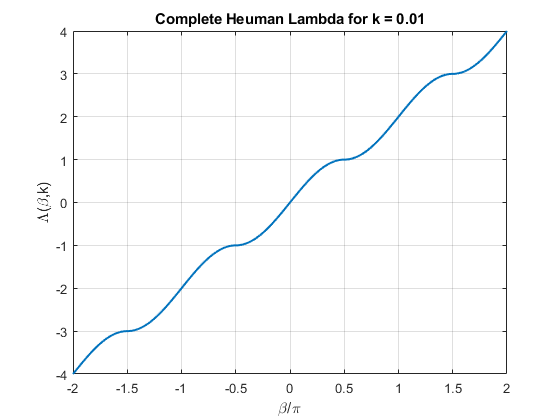

figure
BETA=-2:0.01:2;
k = 0.01;
plot(BETA,HeumanLambda(pi*BETA,k),'LineWidth',1.5)
xlabel('\beta/\pi')
ylabel('\Lambda(\beta,k)')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Complete Heuman Lambda for k = %g',k))
grid on

**Example 2**

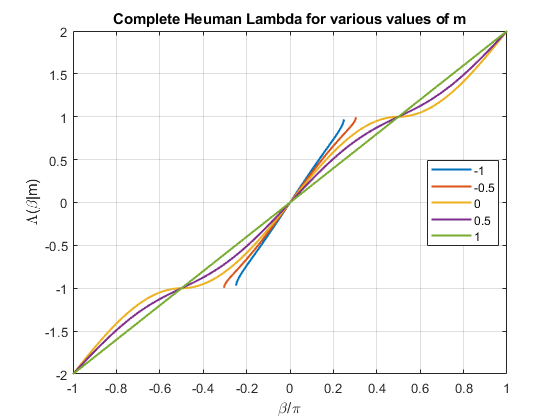

figure
BETA = -1:0.001:1;
M = [-1,-0.5,0,0.5,1];
SN = zeros(length(M),length(BETA));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mHeumanLambda(pi*BETA,M(i));
end
plot(BETA,SN,'LineWidth',1.5)
%axis([min(BETA) max(BETA) -1 1])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Complete Heuman Lambda for various values of m')
xlabel('\beta/\pi')
ylabel('\Lambda(\beta|m)')

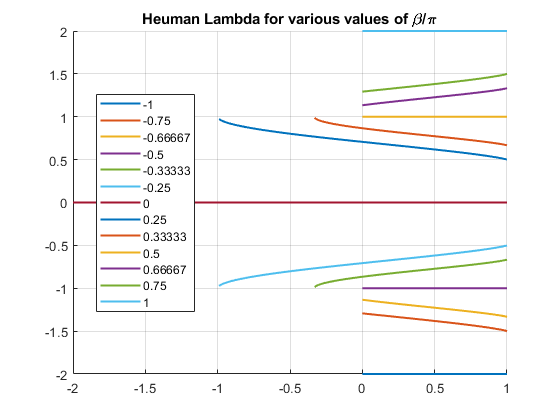

figure
hold on
M = -2:0.01:1;
BETA = [-1,-3/4,-2/3,-1/2,-1/3,-1/4,0,1/4,1/3,1/2,2/3,3/4,1];
SN = zeros(length(BETA),length(M));
clg{length(BETA)}=[];
for i = 1:length(BETA)
     clg{i} = num2str(BETA(i));
    SN(i,:) = mHeumanLambda(pi*BETA(i),M);
end
plot(M,SN,'LineWidth',1.5)
%axis([min(M) max(M) -1.2 1.2])
grid on
legend(clg{1:length(BETA)},'Location','Best')
title('Heuman Lambda for various values of \beta/\pi')
hold off

**Example 3**

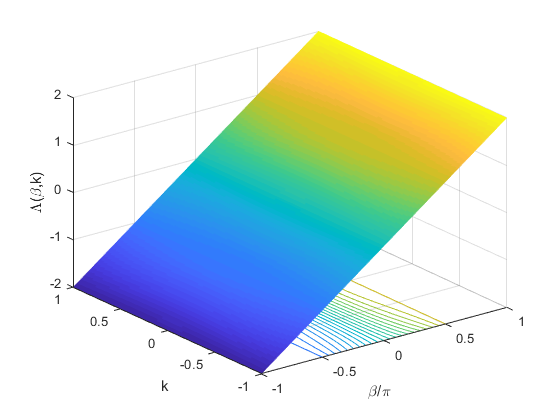

figure
BETA=-1:0.01:1;
k=-1:0.01:1;
[BETA,K]=meshgrid(BETA,k);
hs=surfc(BETA,K,HeumanLambda(pi*BETA,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -1:0.1:1;
caxis([-2 2])
view(3);
xlabel('\beta/\pi')
ylabel('k')
zlabel('\Lambda(\beta,k)')
zlim([-2 2])
grid on

**Example 4**

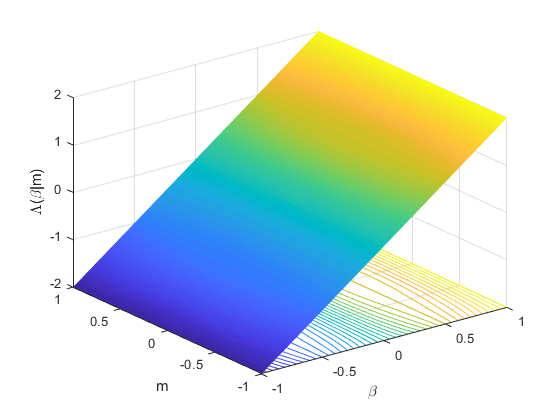

figure
BETA=-1:0.01:1;
m=-1:0.01:1;
[BETA,M]=meshgrid(BETA,m);
hs=surfc(BETA,M,HeumanLambda(pi*BETA,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
view(3)
caxis([-2 2])
xlabel('\beta')
ylabel('m')
zlabel('\Lambda(\beta|m)')
%zlim([-2 2])
grid on

**Example 5**

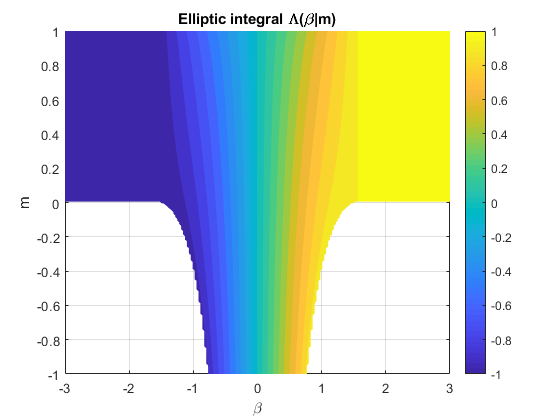

figure
f = @(BETA,m)mHeumanLambda(BETA,m);
fcontour(f,[-3 3 -1 1],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral \Lambda(\beta|m)')
xlabel('\beta')
ylabel('m')
colorbar
grid on

**Example 6**

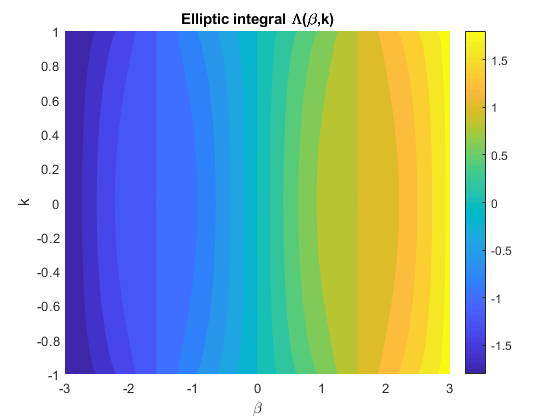

figure
f = @(BETA,k)HeumanLambda(BETA,k);
fcontour(f,[-3 3 -1 1],'Fill','on','LevelList',-3:0.2:3,'MeshDensity',200)
title('Elliptic integral \Lambda(\beta,k)')
xlabel('\beta')
ylabel('k')
colorbar
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] C. Heuman, Tables of Complete Elliptic Integrals, J Math Phys Camb, 20 (1941) 127-206

[2] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions, part

III. Numerische Mathematik 13, 305-315, 1969.

## See Also